## Name: Maria Eva Vazquez

## Date: 10/23/2026

## PID: 6296923

## Quiz 4 : Numerical Integration

**General Instructions:** Complete each question to the best of your abilities.  Include comments in your code to explain your thought process while answering.

**Submission Instructions:** Quiz files should be titled Quiz_X_FirstNameLastName, Ex: Quiz_4_AsadMirza. To convert the MLX file into a PDF go to the Export icon under Live Editor and select "Export to PDF".

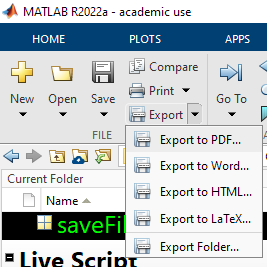

Any scratch paper used should have your name, date, and PID on it and be submitted to me when you finish your quiz.

Question 1 (50%) 

For the function:


$$\frac{\textrm{dy}}{\textrm{dx}}=y+\sin \left(x\right)\;,y\left(0\right)=1$$


The analytical solution is:


$$y=\frac{3}{2}{\mathrm{e}}^x -\frac{\sin \left(x\right)+\cos \left(x\right)}{2}$$


Do the following from $x=0$ to $x=3$ with a step size of $h=0\ldotp 1$

a) (15%) Solve using the Forward Euler Method.

clear; clc; close all;

% % Step 1
h =  0.1;
t = 0:h:3;
y0 = 1;
y(1) = y0;%IC
% Set up function 
f = @(x,y) y + sin(x);


% % Step 2 
s = zeros(size(t)); % Pre-allocate
s(1) = y0;        
for ii = 1:length(t) - 1
    s(ii + 1) = s(ii) + h * f(t(ii), s(ii));
end


% Euler uses this formula
% New Value = Old Value + (Derivative * h)



b) (15%) Solve using the Backward Euler Method.

% % Step 3
s_Back = zeros(size(t));   % >> y_n
s_Back(1) = y0;  
for ii = 1:length(t)-1
    g = @(Y) s_Back(ii) + h * f(t(ii+1), Y) - Y; 
    % Basically:  y_n+1 = y_n + h* f(t_n+1 , y_n+1)
    %    where                       ^t(ii+1) is t_n+1
    s_Back(ii+1) = fzero(g, s_Back(ii));% Solve implicit problem
end


c) (15%) Solve using the Central Euler Method.

% % Step 4
t_C = zeros(1,length(t)); % >> y_n
t_C(1) = y0;
for ii = 1:length(t)-1
    % First, value at the midpoint
    t_mid = t_C(ii) + (h/2) * f(t_C(ii),t_C(ii));   % fix <<<<<<<
    x_mid = t(ii) + h/2;
    % Basically:  y_n+1/2 = y_n + h/2 * f(x_n, y_n)
    %    where                         ^x(ii) >> x_n
    t_C(ii+1) = t_C(ii) + h * f(x_mid,t_mid);
    % Basically:  y_n+1 = y_n + h * f(x_n+1/2, y_n+1/2)
    %    where                       ^x_mid >> x_n+1/2
end



d) (2.5%) Plot the Forward, Backward, Central, and Exact solutions on a single plot with axis labels and a legend.

% % Step 6
y_exact=@(t) y + sin(t);

% % Step 7
figure;
tt = linspace(min(t), max(t), 10000);
plot(tt, y_exact(tt), 'LineWidth', 1.5); % exact
hold on
plot(t, s, '-o', 'MarkerSize', 4, 'LineWidth', 1); % fowards
plot (t,s_Back,'-o', 'MarkerSize', 4, 'LineWidth', 1); % back
plot (t, t_C, '-o', 'MarkerSize', 4, 'LineWidth', 1); % central
hold off
xlabel('Time (t)');
ylabel('y(t)');
legend ('Exact','Forwards','Backwards','Central','Location','best');
title('Euler vs Exact Solution');
grid on

e) (2.5%) Show the graph of the absolute error of the approximation with $h$ between 0.001 and 1 at $x=3$

% % Step 5
t_eval = 3;                                 % time to evaluate error
idx = find(abs(t - t_eval) < 1e-12, 1);      % index closest to t = 3
err_BE = abs(s_Back(idx) - y_exact(t_eval)); % absolute error Back
err_FE = abs(s(idx) - y_exact(t_eval)); % absolute error Forw
err_CE = abs(t_C(idx) - y_exact(t_eval)); % absolute error Cent
fprintf('Backward Euler absolute error at t = %.2f: %.6e\n', t_eval, err_BE);
fprintf('Forward Euler absolute error at t = %.2f: %.6e\n', t_eval, err_FE);
fprintf('Central Euler absolute error at t = %.2f: %.6e\n', t_eval, err_CE);

% % Step 6
h_values = linspace(0.001, 1, 10000) % step size
%Need two loops !!
errors_y = zeros(size(h_values));
t_end = 3; % we stop at y(3) aka x=3

for ii = 1:length(h_values)               %<<< LOOP 1
    h = h_values(ii);    % Current h
    t = 0:h:t_end;      % Time vector

    y_error = zeros(1, length(t)); % pre-allo for loop 2
    y_error(1) = 1; % initial for loop 2

    for jj = 1:length(t)-1                %<<< LOOP 2
         y_error(jj+1) = y_error(jj) + h * f(t(jj),y_error(jj)); % forwards
    end
    errors_y(ii) = (abs(y_exact) -  y_error(end));  % absolute errors at t = 3
end

% % Step 7
figure; 
semilogx(h_values, errors_y, '-o');
xlabel('Step size h');
ylabel('Absolute Error at t = 2');
title('Euler Convergence');
grid on;

Question 2 (50%) 

Cancer immunotherapy research uses mathematical models to study how the immune system fights a tumor. Let T(t) be the number of tumor cells and E(t) the number of immune effector cells (for example, cytotoxic T cells) in the tissue, both in millions of cells, at time t in days. Assume the two populations evolve according to the following system of differential equations:


$$\frac{\mathrm{d}T}{\mathrm{d}t}=rT\left(1-\frac{T}{K}\right)-aTE$$



$$\frac{\mathrm{d}E}{\mathrm{d}t}=-mE+cTE$$


where the parameters are:

- *r* = 0.5 per day: tumor growth rate

- *K* = 100 million cells: carrying capacity of the tissue

- *a* = 0.02 per million cells per day: rate at which immune cells kill tumor cells

- *m* = 0.3 per day: death rate of immune cells

- *c* = 0.01 per million cells per day: rate at which contact with tumor cells stimulates immune cell growth

Assume that the initial populations are *T*(0) = 50 million cells and *E*(0) = 10 million cells.

a) (5%) Starting from the differential equations for $T$ and $E$, discretize and write (but do not solve) the corresponding **difference equations** using the **Forward Euler method** with a time step of $h$. Use the Equation tool under the Insert tab.


$$\mathrm{dTdt}=0\ldotp 5*T\left(1-\frac{T}{100}\right)-0\ldotp 02*T*E$$



$$\mathrm{dEdt}=-0\ldotp 3*E+0\ldotp 01*T*E$$


h = ???  ;% Step size

x = 0:h:3; % t_n

% % Step 2

t = zeros(1,length(x)); % >> y_n

t(1) = y0;

for ii = 1:length(x)-1

    t(ii+1) = t(ii) + h * f(x(ii),t(ii));

    % Basically:  y_n+1 = y_n + h * f(t_n, y_n)

    %    where                       ^x(ii) is t_n

end

b) (25%) Use the Forward Euler method to approximate the tumor and immune cell populations from t = 0 to t = 60 days, using the parameter values listed above. Use a step size of $h=0.01$.

% Initial populations (billions)
T0 = 50; % In millions
E0= 10; % In millions
h = 0.01;
x = 0:h:60;  

%Store
PT = zeros(1,length(x));
PT = T0;
PE = zeros(1,length(x));
PE= E0;

r = 0.5;
K = 100;
a = 0.02;
m = 0.3 ;
c = 0.01 ;

% Functions 
dT= @ (pT, pE) r*T* (1-(T/K))- a*T*E;
dE =@(pT, pE) -0.3*E + 0.01*T*E;

for ii = 1:length(x) - 1
    PT(ii + 1) = PT(ii) + h * dT(PT(ii), PE(ii)); % tumors
    PE(ii + 1) = PE(ii) + h * dE(PT(ii), PE(ii)); % immune cell
end

Unrecognized function or variable 'T'.

Error in Quiz_4_MariaEVazquez>@(pT,pE)0.5.*T*(1-(T/100))-0.02.*T*E (line 115)
dT= @ (pT, pE) 0.5.*T* (1-(T/100))- 0.02.*T*E;

c) (15%) Plot the trajectories of the tumor and immune cell populations as a function of time, using the results from (b). Include axis labels (with units) and a legend.

figure
plot(x,PT,'linewidth',2); % tumor
hold on
plot (x,PE,'color',"g",'linewidth',2); % immune cells
hold off
xlabel('Time (h)')
ylabel('Population (billion)')
legend('Tumors','Immune Cells', 'Location','best')
grid on

d) (5%) Discuss the behavior of the tumor and immune cell populations over time. Do the populations oscillate, grow without bound, die out, or settle to a steady value? Explain why in terms of the interaction between the two cell types. Maximum of 4 sentences.

**The immune cell population grows exponientally the closer to 60 days. The tumors are not visible in the graph, so unless they perfectly align with the immune cell population (unlikely), there was a coding issue. Based on the data of the problem, I can make an educate guesss. **